clear;
clc;

odom = Odometry();

start_ticks = 760;
end_ticks = 846;
steer_angle = 45;


odom.update(start_ticks, steer_angle);


pose_backlog = [];
xy_backlog = [];
for i=760:846
    odom.update(i, steer_angle);
    pose_backlog = [pose_backlog ; odom.odom_pose];
    xy_backlog = [xy_backlog ; [odom.odom_pose.get_translation.get_x odom.odom_pose.get_translation.get_y]];
end


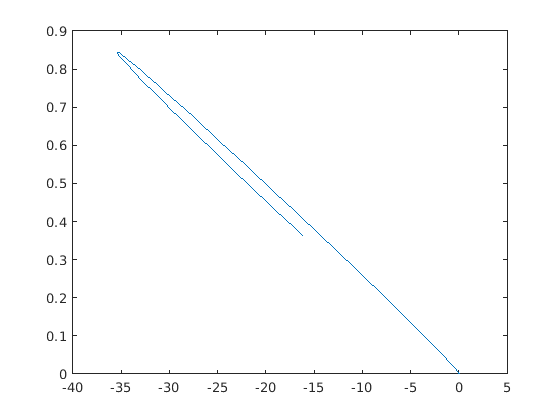

plot(xy_backlog(:,1),xy_backlog(:,2));